% evaluacion_ruta_cobertura.mlx

# Evaluacion de rutas utilizando un planificador de cobertura.

by AG ariel.guerrero@uc.edu.py 27-07-2024

## Referencia:

[1] Torres, Marina, David A. Pelta, José L. Verdegay, and Juan C. Torres.   “Coverage Path Planning with Unmanned Aerial Vehicles for 3D Terrain Reconstruction.” Expert Systems with Applications 55 (August 2016): 441–51. [https://doi.org/10.1016/j.eswa.2016.02.007.](https://doi.org/10.1016/j.eswa.2016.02.007.)

 [2] Li, Yan, Hai Chen, Meng Joo Er, and Xinmin Wang.  “Coverage Path Planning for UAVs Based on Enhanced Exact Cellular Decomposition Method.”  Mechatronics 21, no. 5 (August 2011): 876–85. [https://doi.org/10.1016/j.mechatronics.2010.10.009.](https://doi.org/10.1016/j.mechatronics.2010.10.009.)

 [3]"Optimally Survey and Customize Coverage of Region of Interest" disponible en   [https://la.mathworks.com/help/uav/ug/optimally-survey-and-customize-coverage-of-region-of-interest-using-coverage-planner.html](https://la.mathworks.com/help/uav/ug/optimally-survey-and-customize-coverage-of-region-of-interest-using-coverage-planner.html)

 [4]"Execute Coverage Plan Using UAV Mission" disponible en [https://la.mathworks.com/help/uav/ref/uavcoverageplanner.html](https://la.mathworks.com/help/uav/ref/uavcoverageplanner.html)

 [5] Zhang, C. (2020). Area Coverage with Unmanned Aerial Vehicles Using Reinforcement Learning. [https://github.com/zcczhang/UAV_Coverage](https://github.com/zcczhang/UAV_Coverage)

[6] Nam, L. H., Huang, L., Li, X. J., & Xu, J. F. (2016, April). An approach for coverage path planning for UAVs. In 2016 IEEE 14th international workshop on advanced motion control (AMC) pp. 411-416). IEEE.

## Antecedentes

 La planificación de cobertura (CPP - Coverture Path Planning) es el proceso de encontrar un plan de ruta óptimo para que un UAV inspeccione toda la región de una determinada área geográfica.

 Para inspeccionar una región, un UAV típicamente vuela en una dirección y utiliza giros en ángulo recto para alternar la dirección.  Una buena opción es descomponer el área en subáreas convexas y luego, puedes elegir de manera óptima una estrategia de cobertura que sea mejor para cada subregión y, posteriormente, conectar las rutas para completar la misión.

clear variables
close all
clc

## Defina la region de interes

Para comenzar la planificación de cobertura, primero debes definir la región de interés como un polígono o un conjunto de polígonos. Primero, crea el eje geográfico, establece los  límites de latitud y longitud, y calcula la media de los límites para obtener el geocentro  del área visualizada. Establece la altura de referencia en 200 metros.

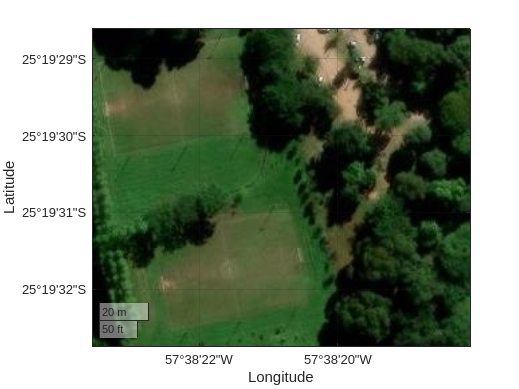

fig = figure('Name', 'Mission-Creator');
gax = geoaxes(fig);
% Si esto funciona, intenta agregar el basemap
set(gax, 'Basemap', 'satellite');
latlimits = [-25.3257611 -25.3246139]; % ROI-01 y R0I-02
lonlimits = [-57.6396222 -57.6386111];
geolimits(latlimits,lonlimits);
geocenter = [mean(latlimits) mean(lonlimits) 0];
refHeight = 3; % Altitud de vuelo del Dron
hold on

Defina los vértices del polígono de manera interactiva seleccionando puntos en el mapa, o puedes usar vértices predefinidos almacenados en predefinedROI.mat para definir el polígono, la ubicación de despegue y la ubicación de aterrizaje. Por defecto, este script utiliza  puntos predefinidos. Para definir el polígono de manera interactiva, establece interactiveROI en true.

interactiveROI = false;
load predefinedROI.mat
GraficarDespegueROIAterrizaje(gax,takeoffLat,takeoffLon,landLat,landLon,llapoints);

###  Dividir la region de interes en subregiones

Para inspeccionar óptimamente un área compleja, primero hay que descomponer  la región en áreas convexas más simples. 

subAreasEN = coverageDecomposition(xyzpoints(:,1:2));
% Creacion de un array de celdas para las nuevas areas.
subAreasLLA = cell(1,numel(subAreasEN));

% Conversion de las coordenadas locales ENU a coordenadas geodesicas.
for i = 1:numel(subAreasEN)
    % Altura de referencia a las coordenadas ENU locales
    altitude = refHeight * ones(size(subAreasEN{i}, 1), 1);
    localENU = [subAreasEN{i}(:,1), subAreasEN{i}(:,2), altitude];

    % Convierte las coordenadas locales ENU a coordenadas geodescias LLA
    % subArea = enu2lla(localENU, geocenter, "flat");
    subArea = ned2lla(localENU, geocenter, "flat"); % PX4
    % Almacena las coordenadas geodesicas LLA en el array de celdas
    subAreasLLA{i} = subArea(:,1:2);
end

### Crear el espacio de cobertura y planificar la ruta para la ROI

El objetivo es inspeccionar optimamente cada subregion minimizando el numero de giros y la distancia de conexion entre subregiones. La distancia de conexion es la distancia que el UAV debe recorrer para llevar al siguiente poligono a inspeccionar.

#### Crear el espacio de cobertura

cs = uavCoverageSpace(Polygons=subAreasLLA, ...
                      UnitWidth=4, ...
                      Sidelap=0, ...
                      ReferenceHeight=refHeight, ...
                      UseLocalCoordinates=false, ...
                      ReferenceLocation=geocenter);

#### Mostrar el espacio de cobertura en los ejes geográficos

ax = cs.show(Parent=gax, LineWidth=1.25);
%% Crear la region de cobertura y planificar la ruta

% Crear el planificador de cobertura 
cp = uavCoveragePlanner(cs);
% Planificar la ruta de cobertura
[wpts,solnInfo] = plan(cp,[takeoffLat takeoffLon 0],[landLat landLon 0]); 


#### Mostrar  la ruta de cobertura en el espacio de ruta de cobertura  en el espacio de cobertura

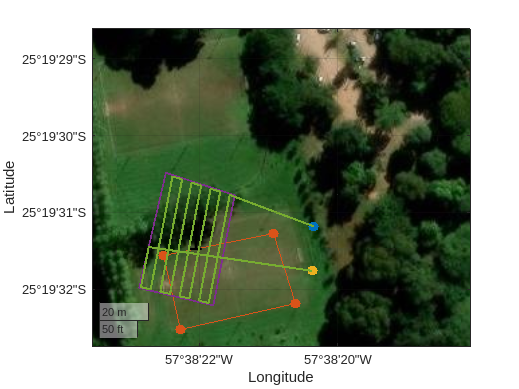

path1 = geoplot(gax, wpts(:,1), wpts(:,2), 'LineWidth', 1.5);
hold off;

#### Verificar el costo de transicion en metros

% Este valor representa la distancia total que el UAV debe recorrer entre los polígonos, 
% incluyendo la distancia desde la ubicación de despegue al primer polígono 
% y desde el último polígono hasta la ubicación de aterrizaje

connectionDistancePath1 = solnInfo.TransitionCost;

### Personalizando la region de cobertura

####  4.1 Personalizacion del patron de barrido

Aunque el planificador determina automaticamente el patron de barrido en cada subregion, se puede ajustar manualmente para mejorar la cobertura dependiendo del tipo de aplicacion.

cs.setCoveragePattern(1,SweepAngle=90); 

En el ejemplo de referencia [1], el angulo de barrido de los poligonos 2 y 3 se establece en 90 grados para alinearse mejor con la orientacion deseada

cs.setCoveragePattern(2,SweepAngle=90); 

Error using uavCoverageSpace/setCoveragePattern (line 271)
Specified polygon index exceeds the maximum number of polygons.

cs.setCoveragePattern(3,SweepAngle=90);


#### 4.2 Optimizacion del punto de inicio

En el ejemplo de referencia [1], el poligono 3 parece ser mejor punto de  inicio para la mision de cobertura, ya que esto minimizara la distancia que el Dron necesita viajar fuera de la mision de cobertura, optimizando el uso de bateria y tiempo.

cp.SolverParameters.StartingArea = 3; % Solo 1 region


#### 4.3 Replanificacion de la cobertura

Despues de ajustar el angulo de barrido y el area de inicio, se vuelve a planificar la ruta de cobertura con estos nuevos parametros. Finalmente, se elimina la ruta anterior y se traza la nueva ruta de cobertura en el grafico para visualizar el nuevo plan de vuelo.

% Replanificar la ruta de cobertura
[~,~] = plan(cp,[takeoffLat takeoffLon 0],[landLat landLon 0]);
landLat = takeoffLat; % Retorna al punto de despegue
landLon = takeoffLon;
 [wpts,custSoln] = plan(cp,[takeoffLat takeoffLon 0],[landLat landLon 0]);

% Remover la ruta anterior y actualizar a la nueva ruta
delete(path1);
hold on
h2 = geoplot(gax,wpts(:,1),wpts(:,2),LineWidth=1.5);
hold off

% Verificar el costo de transicion
% connectionDistancePath2 = custSoln.TransitionCost


### Proximos pasos

 Exportar el patron de navegacion compatible con QGC/ArduPilot Archivo de waypoints en el formato QGroundControl Waypoint List (QGC WPL) para planificar una misión de un UAV (dron).


exportWaypointsPlan(cp,solnInfo,"misionLED.waypoints");
% exportWaypointsPlan(cp,custSoln,"customCoverage.waypoints"); %ver [1]


###  Simular la ruta de cobertua usando UAV Mission

Crear una mision y simular la mision

%mission = uavMission(PlanFile="customCoverage.waypoints",Speed=5,InitialYaw=90);
%SimularUAVMision(mission,geocenter)